# Reto F3001C

Max Eduardo Garcia Esquivel - A01236070.

Convinaciones con condicion:

    Wg 1 - Modo 14, Modo 15

    Wg 3 - Modo 15

   %Code Variables
%Sizes
sXs = [1000,930,475,405];
sYs = [325,235,955,730];

%Paths
SuperiorPath = "./../Phase4V2/Sweeps/Matlab/";
FundamentalPath = "./../Phase3/Sweeps/Matlab/";

%Modes
Superior = "Waveguide%i_%i_532_Mode%i";
Fundamental = "Waveguide%i_%i_1596";
ModesSup = [15,9,19,12];

warning('off','MATLAB:polyfit:RepeatedPointsOrRescale')

## Waveguide selector:

sel = 1;
nmodes = ModesSup(sel);
mode = 14;
disp("Selected waveguide:")

Selected waveguide:


disp("   Size: "+num2str(sXs(sel))+"x"+num2str(sYs(sel)));

   Size: 1000x325


disp("   Mode: "+num2str(mode));

   Mode: 14


 

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);
file = sprintf(Superior,sXs(sel),sYs(sel),mode);
load(SuperiorPath+file);
wgSuperior = waveguide(lambda,neff);

lphLim = [min(wgFundamental.lambdaData) max(wgFundamental.lambdaData)];
lpLim = [min(wgSuperior.lambdaData) max(wgSuperior.lambdaData)];
lpm = lpLim(1);
lpM = lpLim(2);

## Phase Matching

size=50;

dW = 1e8;

wn = linspace(2.*pi.*3.*10.^8/lphLim(1),2.*pi.*3.*10.^8/lphLim(2),6);

disp("Pump wavelength: "+num2str(lpLim(1))+"-"+num2str(lpLim(2)));

Pump wavelength: 0.51-0.532


disp("Photon wavelength: "+num2str(lphLim(1))+"-"+num2str(lphLim(2)));

Photon wavelength: 1.53-1.596


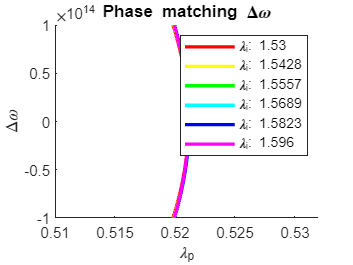

wp = linspace(2.*pi.*3.*10.^8./lpLim(1),2.*pi.*3.*10.^8./lpLim(2),size);
dw = linspace(dW,-dW,size);
[WP,DW] = meshgrid(wp,dw);

figure
hold on
leg = {};
for n = 1:6
    wi = wn(n);
    wr = DW+(WP-wi)/2;
    ws = WP-wi-wr;
    DK = wgSuperior.kwFun(WP)-(wgFundamental.kwFun(wi)+wgFundamental.kwFun(wr)+wgFundamental.kwFun(ws));
    switch n
        case 1
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'r','LineWidth',2);
        case 2
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'y','LineWidth',2);
        case 3
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'g','LineWidth',2);
        case 4
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'c','LineWidth',2);
        case 5
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'b','LineWidth',2);
        case 6
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'m','LineWidth',2);
    end

    leg(end+1) = {"\lambda_i: "+num2str(2.*pi.*3.*10.^8/wi)};
end

xlabel("\lambda_p");
ylabel("\Delta\omega");
title("Phase matching \Delta\omega")

legend(leg)

## Phase Matching (Zoomed)

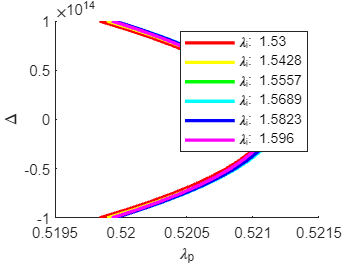

minl = 0.5195;
maxl = 0.5215;

size=25;

dW = 100000000;

wp = linspace(2.*pi.*3.*10.^8./(minl),2.*pi.*3.*10.^8./(maxl),size);
dw = linspace(dW,-dW,size);
[WP,DW] = meshgrid(wp,dw);

figure
hold on
leg = {};
for n = 1:6
    wi = wn(n);
    wr = DW+(WP-wi)/2;
    ws = WP-wi-wr;
    DK = wgSuperior.kwFun(WP)-(wgFundamental.kwFun(wi)+wgFundamental.kwFun(wr)+wgFundamental.kwFun(ws));
    switch n
        case 1
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'r','LineWidth',2);
        case 2
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'y','LineWidth',2);
        case 3
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'g','LineWidth',2);
        case 4
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'c','LineWidth',2);
        case 5
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'b','LineWidth',2);
        case 6
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'m','LineWidth',2);
    end

    leg(end+1) = {"\lambda_i: "+num2str(2.*pi.*3.*10.^8/wi)};
end

xlabel("\lambda_p");
ylabel("\Delta");

legend(leg)

## Comprobation of Δk=0 at degenerancy

size=50;

lp = linspace(lpLim(1),lpLim(2),size);
wp = 2.*pi.*3.*10.^8./lp;
ws = wp./3;
leg = {};

figure
hold on

dk0s = [];

dk = wgSuperior.kwFun(wp)-(3*wgFundamental.kwFun(ws));

if(min(dk)<=0 && max(dk)>=0)
    dk0s = [dk0s i];
end

plot(lp,dk);
leg(end+1) = {"Mode"'+num2str(mode)};

if ~isequal(dk0s,[])
    strDk0s = "Mode with dK=0";
else
    strDk0s = "No mode with dK=0";
end

disp(strDk0s)

Mode with dK=0


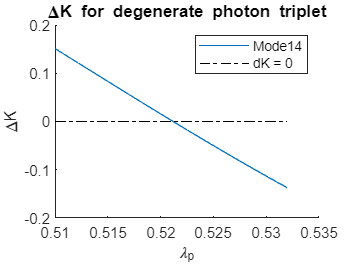


plot([lpLim(1),lpLim(2)],[0,0],'k-.')
leg(end+1) = {"dK = 0"};

xlabel("\lambda_p");
ylabel("\DeltaK");

legend(leg);
title("\DeltaK for degenerate photon triplet");

## Obtain wavelengths for energy and momentum conservation

definition = 0.000001;

lphLim = [min(wgFundamental.lambdaData) max(wgFundamental.lambdaData)];
lpLim = [min(wgSuperior.lambdaData) max(wgSuperior.lambdaData)];
lp = [lpLim(1):definition:lpLim(2)];
wp = 2.*pi.*3.*10.^8./lp;
ws = wp./3;
leg = {};

figure
hold on

dk0s = [];

dk = wgSuperior.kwFun(wp)-(3*wgFundamental.kwFun(ws));

ind = find(min(abs(dk))==abs(dk));
disp("Value with dk=0, Pump: w="+num2str(wp(ind))+", l="+num2str(lp(ind))+", dk="+num2str(dk(ind)));

Value with dk=0, Pump: w=3616651941.6293, l=0.52119, dk=-3.8399e-06


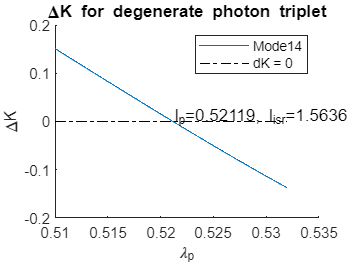


phlp = lp(ind);
phlph = lp(ind)*3;

plot(lp,dk);
leg(end+1) = {"Mode"'+num2str(mode)};

plot([lpLim(1),lpLim(2)],[0,0],'k-.');
leg(end+1) = {"dK = 0"};

text(lp(ind),dk(ind)+0.01,"l_p="+num2str(lp(ind))+", l_{isr}="+num2str(lp(ind)*3));

xlabel("\lambda_p");
ylabel("\DeltaK");

legend(leg);
title("\DeltaK for degenerate photon triplet");

## Data for photons

Wg1, M14: lp = 0.52119, lisr=1.56357. (σ=2e12, L=300μm)

Wg1, M15: lp = 0.51189, lisr=1.53567.

Wg3, M15: lp = 0.51971, lisr=1.55913.

## Phase Matching Function


$$\phi \left(\omega_r ,\omega_s ,\omega_i \right)=\textrm{sinc}\left\lbrack L\frac{\Delta k\left(\omega_r ,\omega_s ,\omega_i \right)}{2}\right\rbrack \exp \left\lbrack \textrm{iL}\frac{\Delta k\left(\omega_r ,\omega_s ,\omega_i \right)}{2}\right\rbrack$$



$$\Delta k\left(\omega_r ,\omega_s ,\omega_i \right)=k_p \left(\omega_r +\omega_s +\omega_i \right)-k_r \left(\omega_r \right)-k_s \left(\omega_s \right)-k_i \left(\omega_i \right)-\Phi_{\textrm{NL}}$$


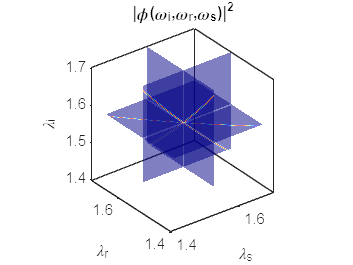

size = 400;

phwph = (2*pi*3*10^8)/phlph;
dw = 1e8;

% Linear vectors
wph = linspace(phwph-dw,phwph+dw,size);
wphV = linspace(phwph-dw,phwph+dw,size/4);
mwph = phwph;
[WPHX,WPHY] = meshgrid(wph,wph);

sigma = 4e12;
lp0 = phlp;
wp0 = 2*pi*3*10^8/lp0;

L = 3e2;

figure
hold on
zlabel("\lambda_i");xlabel("\lambda_s");ylabel("\lambda_r");
colormap(jet);

% x/y plane (ws,wr)
wi = WPHX.*0+mwph; ws = WPHX; wr = WPHY;
dkrsi = wgSuperior.kwFun(wi+ws+wr)-wgFundamental.kwFun(wi)-wgFundamental.kwFun(ws)-wgFundamental.kwFun(wr)+PNL;
sinPh = sinc(L*dkrsi/2);
expPh = exp(1i*L*dkrsi/2);
fpm = sinPh.*expPh;
surf((2*pi*3*10^8)./ws,(2*pi*3*10^8)./wr,(2*pi*3*10^8)./wi,'cdata',abs(fpm).^2), shading interp

% x/z plane (ws,wi)
wi = WPHY; ws = WPHX; wr = WPHX.*0+mwph;
dkrsi = wgSuperior.kwFun(wi+ws+wr)-wgFundamental.kwFun(wi)-wgFundamental.kwFun(ws)-wgFundamental.kwFun(wr)+PNL;
sinPh = sinc(L*dkrsi/2);
expPh = exp(1i*L*dkrsi/2);
fpm = sinPh.*expPh;
surf((2*pi*3*10^8)./ws,(2*pi*3*10^8)./wr,(2*pi*3*10^8)./wi,'cdata',abs(fpm).^2), shading interp

% y/z plane (wr,wi)
wi = WPHY; ws = WPHX.*0+mwph; wr = WPHX;
dkrsi = wgSuperior.kwFun(wi+ws+wr)-wgFundamental.kwFun(wi)-wgFundamental.kwFun(ws)-wgFundamental.kwFun(wr)+PNL;
sinPh = sinc(L*dkrsi/2);
expPh = exp(1i*L*dkrsi/2);
fpm = sinPh.*expPh;
surf((2*pi*3*10^8)./ws,(2*pi*3*10^8)./wr,(2*pi*3*10^8)./wi,'cdata',abs(fpm).^2), shading interp

alpha(0.5);
view(3);

set(gcf,'Color',[1,1,1]);
set(gca,'TickDir','out','TickLength',[0.015 0.015]);
%set(gca,'FontSize',18,'FontName','arial');
box on
axis square

title("|\phi(\omega_i,\omega_r,\omega_s)|^2");

## Pump Spectral Amplitude Function


$$\alpha \left(\omega_p \right)=\frac{2^{\frac{1}{4}} }{\pi^{\frac{1}{4}} \sqrt{\sigma \;}}e^{-\frac{{\left(\omega_p -\omega_{\textrm{p0}} \right)}^2 }{\sigma^2 }}$$


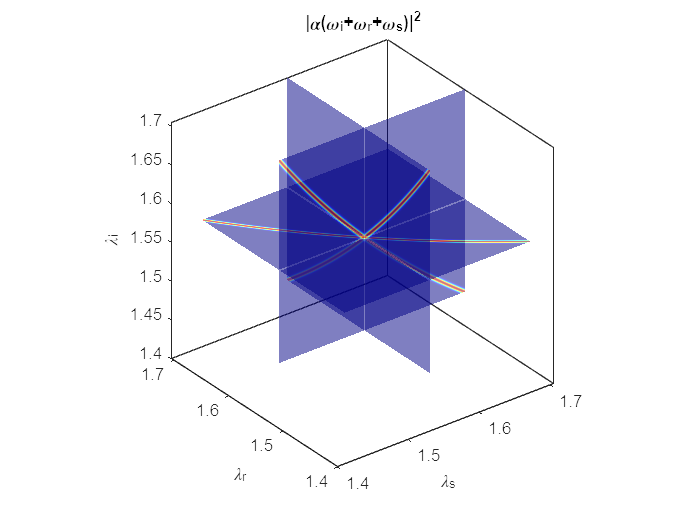

figure
hold on
zlabel("\lambda_i");xlabel("\lambda_s");ylabel("\lambda_r");
colormap(jet);

% x/y plane (ws,wr)
wi = WPHX.*0+mwph; ws = WPHX; wr = WPHY;
ca = 2^(1/4)/(pi^(1/4)*sigma);
wpw0 = (ws+wr+wi-wp0)*10^6;
awp = ca*exp(-(wpw0).^2/sigma^2);
surf((2*pi*3*10^8)./ws,(2*pi*3*10^8)./wr,(2*pi*3*10^8)./wi,'cdata',abs(awp).^2), shading interp

% x/z plane (ws,wi)
wi = WPHY; ws = WPHX; wr = WPHX.*0+mwph;
ca = 2^(1/4)/(pi^(1/4)*sigma);
wpw0 = (ws+wr+wi-wp0)*10^6;
awp = ca*exp(-(wpw0).^2/sigma^2);
surf((2*pi*3*10^8)./ws,(2*pi*3*10^8)./wr,(2*pi*3*10^8)./wi,'cdata',abs(awp).^2), shading interp

% y/z plane (wr,wi)
wi = WPHY; ws = WPHX.*0+mwph; wr = WPHX;
ca = 2^(1/4)/(pi^(1/4)*sigma);
wpw0 = (ws+wr+wi-wp0)*10^6;
awp = ca*exp(-(wpw0).^2/sigma^2);
surf((2*pi*3*10^8)./ws,(2*pi*3*10^8)./wr,(2*pi*3*10^8)./wi,'cdata',abs(awp).^2), shading interp

alpha(0.5);
view(3);

set(gcf,'Color',[1,1,1]);
set(gca,'TickDir','out','TickLength',[0.015 0.015]);
%set(gca,'FontSize',18,'FontName','arial');
box on
axis square

title("|\alpha(\omega_i+\omega_r+\omega_s)|^2");

## Joint Spectral Intensity (JSI) (Zoomed)


$$F\left(\omega_r ,\omega_s ,\omega_i \right)=\alpha \left(\omega_r +\omega_s +\omega_i \right)\phi \left(\omega_r ,\omega_s ,\omega_i \right)$$


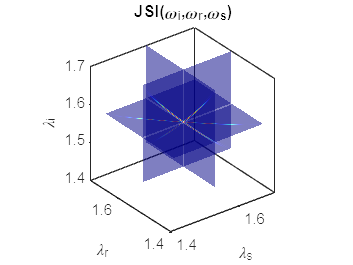

figure
hold on
zlabel("\lambda_i");xlabel("\lambda_s");ylabel("\lambda_r");
colormap(jet);

% x/y plane (ws,wr)
wi = WPHX.*0+mwph; ws = WPHX; wr = WPHY;
ca = 2^(1/4)/(pi^(1/4)*sigma);
wpw0 = (ws+wr+wi-wp0)*10^6;
awp = ca*exp(-(wpw0).^2/sigma^2);
dkrsi = wgSuperior.kwFun(wi+ws+wr)-wgFundamental.kwFun(wi)-wgFundamental.kwFun(ws)-wgFundamental.kwFun(wr)+PNL;
sinPh = sinc(L*dkrsi/2);
expPh = exp(1i*L*dkrsi/2);
fpm = sinPh.*expPh;
JSI = awp.*fpm;
surf((2*pi*3*10^8)./ws,(2*pi*3*10^8)./wr,(2*pi*3*10^8)./wi,'cdata',abs(JSI).^2), shading interp

% x/z plane (ws,wi)
wi = WPHY; ws = WPHX; wr = WPHX.*0+mwph;
ca = 2^(1/4)/(pi^(1/4)*sigma);
wpw0 = (ws+wr+wi-wp0)*10^6;
awp = ca*exp(-(wpw0).^2/sigma^2);
dkrsi = wgSuperior.kwFun(wi+ws+wr)-wgFundamental.kwFun(wi)-wgFundamental.kwFun(ws)-wgFundamental.kwFun(wr)+PNL;
sinPh = sinc(L*dkrsi/2);
expPh = exp(1i*L*dkrsi/2);
fpm = sinPh.*expPh;
JSI = awp.*fpm;
surf((2*pi*3*10^8)./ws,(2*pi*3*10^8)./wr,(2*pi*3*10^8)./wi,'cdata',abs(JSI).^2), shading interp

% y/z plane (wr,wi)
wi = WPHY; ws = WPHX.*0+mwph; wr = WPHX;
ca = 2^(1/4)/(pi^(1/4)*sigma);
wpw0 = (ws+wr+wi-wp0)*10^6;
awp = ca*exp(-(wpw0).^2/sigma^2);
dkrsi = wgSuperior.kwFun(wi+ws+wr)-wgFundamental.kwFun(wi)-wgFundamental.kwFun(ws)-wgFundamental.kwFun(wr)+PNL;
sinPh = sinc(L*dkrsi/2);
expPh = exp(1i*L*dkrsi/2);
fpm = sinPh.*expPh;
JSI = awp.*fpm;
surf((2*pi*3*10^8)./ws,(2*pi*3*10^8)./wr,(2*pi*3*10^8)./wi,'cdata',abs(JSI).^2), shading interp

alpha(0.5);
view(3);

set(gcf,'Color',[1,1,1]);
set(gca,'TickDir','out','TickLength',[0.015 0.015]);
%set(gca,'FontSize',18,'FontName','arial');
box on
axis square

title("JSI(\omega_i,\omega_r,\omega_s)");

## Intensities Proyected


$$I_2 \left(\omega_r ,\omega_s \right)=\int d\omega_i \;|F\left(\omega_r ,\omega_s ,\omega_i \right)|^2$$



$$I_1 \left(\omega_r \right)=\int d\omega_s \int d\omega_i \;|F\left(\omega_r ,\omega_s ,\omega_i \right)|^2$$


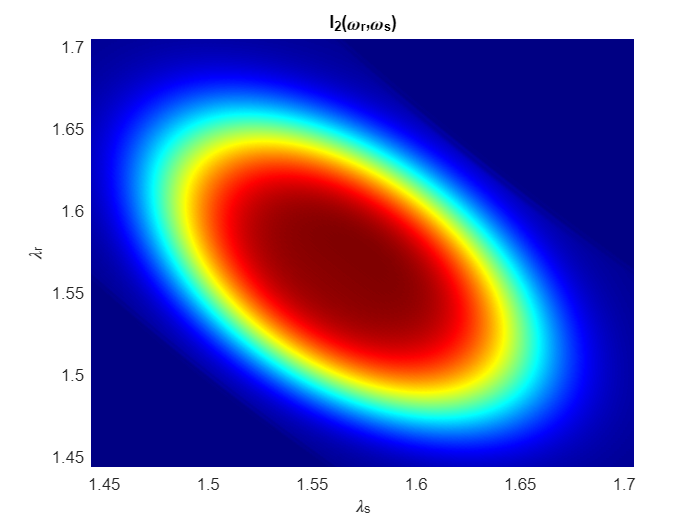

I2 = 0;
Dwph = wphV(2)-wphV(1);

% x/y plane (ws,wr)
WPH0 = WPHX.*0;
ws = WPHX; wr = WPHY;
ca = 2^(1/4)/(pi^(1/4)*sigma);

for mwph = wphV
    wi = WPH0+mwph; 
    wpw0 = (ws+wr+wi-wp0)*10^6;
    awp = ca*exp(-(wpw0).^2/sigma^2);
    dkrsi = wgSuperior.kwFun(wi+ws+wr)-wgFundamental.kwFun(wi)-wgFundamental.kwFun(ws)-wgFundamental.kwFun(wr)+PNL;
    sinPh = sinc(L*dkrsi/2);
    expPh = exp(1i*L*dkrsi/2);
    fpm = sinPh.*expPh;
    JSI = awp.*fpm;

    I2 = I2+Dwph.*abs(JSI).^2;
end

figure
pcolor((2*pi*3*10^8)./ws,(2*pi*3*10^8)./wr,I2), shading interp
xlabel("\lambda_s");ylabel("\lambda_r");
colormap(jet);
title("I_2(\omega_r,\omega_s)");

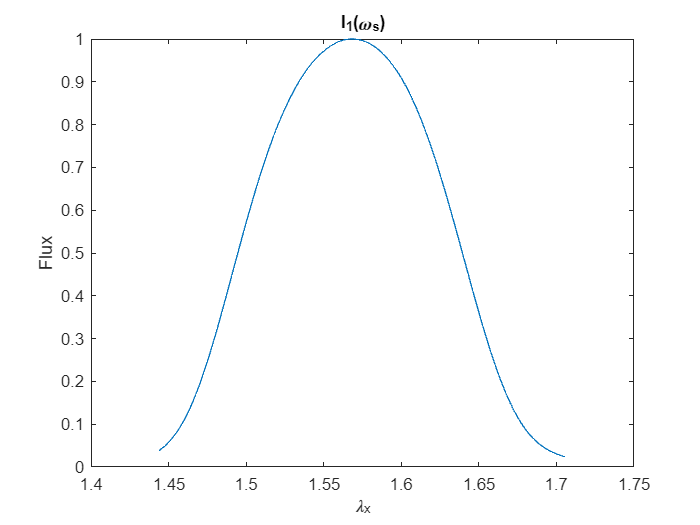

figure
flux = 0;

Dwph = wph(2)-wph(1);
for n = 1:length(I2)
    flux = flux+Dwph.*I2(n,:);
end

plot((2*pi*3*10^8)./wph,flux/max(flux))
title("I_1(\omega_s)");
xlabel("\lambda_x"); ylabel("Flux")